# Assignment 03 - A.A. 2023/24

close all
clear
clc

## 0) Data

Loading data and plotting time histories

% Loading data
load('Data')
t=Data(:,1);
F=Data(:,2);
x=Data(:,3:end);    % displacements in the 4 columns
np=size(x,1);        % number of samples
nj=size(x,2);        % number of displacements

dt=t(2)-t(1);        % acquisition period
fsamp=1/dt;            % sampling frequency
disp(' ')

disp(['Number of sensors: ' num2str(nj)])

Number of sensors: 4


disp(['dt [s]: ' num2str(dt)])

dt [s]: 0.001


disp(['np [-]: ' num2str(np)])

np [-]: 60001


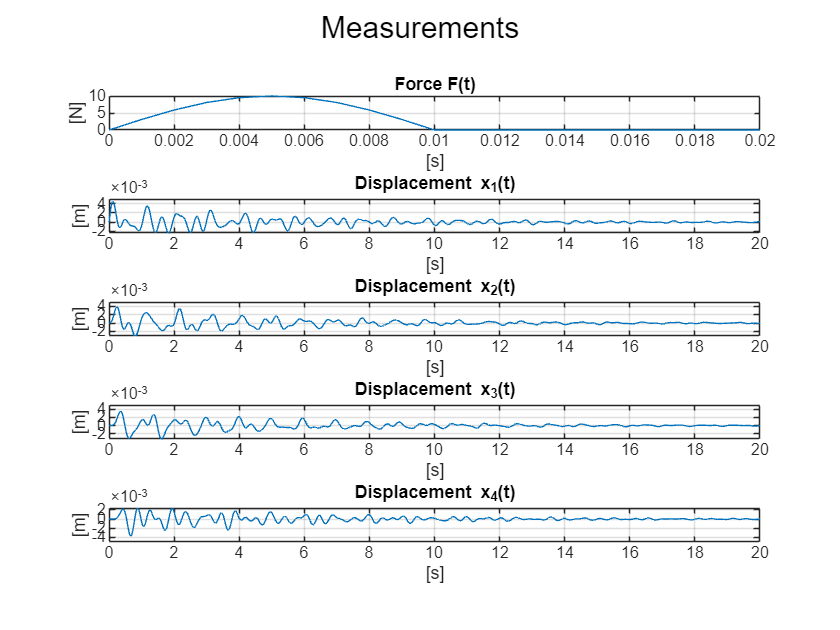


% Plots
figure()
sgtitle("Measurements");

subplot(5, 1, 1);
plot(t, F)
grid on;
title("Force F(t)");
ylabel("[N]");
xlabel("[s]");
xlim([0, 0.02]);

subplot(5, 1, 2);
plot(t, x(:, 1))
grid on;
title("Displacement x_1(t)");
ylabel("[m]");
xlabel("[s]");
xlim([0, 20]);

subplot(5, 1, 3);
plot(t, x(:, 2))
grid on;
title("Displacement x_2(t)");
ylabel("[m]");
xlabel("[s]");
xlim([0, 20]);

subplot(5, 1, 4);
plot(t, x(:, 3))
grid on;
title("Displacement x_3(t)");
ylabel("[m]");
xlabel("[s]");
xlim([0, 20]);

subplot(5, 1, 5);
plot(t, x(:, 4))
grid on;
title("Displacement x_4(t)");
ylabel("[m]");
xlabel("[s]");
xlim([0, 20]);

## 1) Experimental FRF

Plot the "experimental" FRF diagrams.

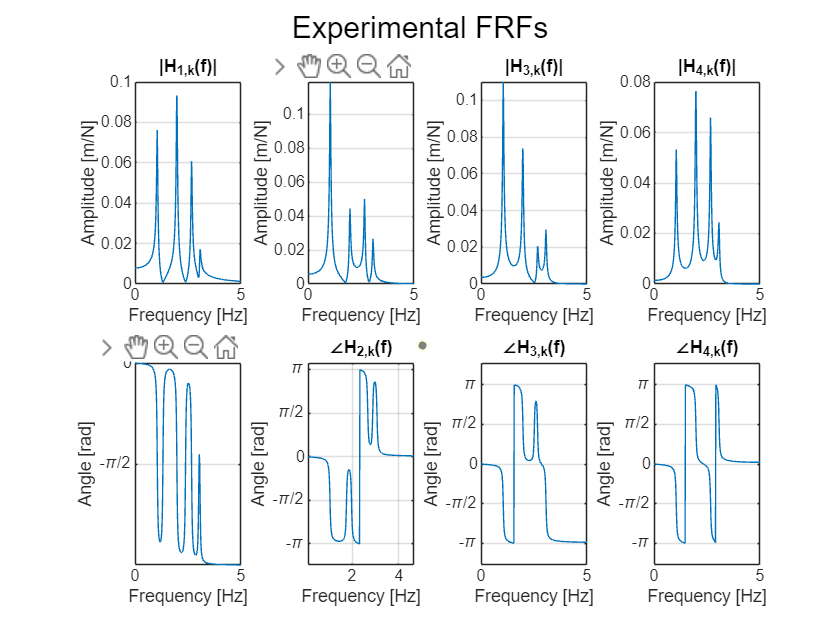

% Force and displacements spectra
[x_fft, frq] = ffg(x, np, dt);
[F_fft, frq] = ffg(F, np, dt);

% Experimental FRFs = ratio output/input
Hjk_exp = x_fft./F_fft;

% Plots
figure()
sgtitle("Experimental FRFs")
for i=1:nj
    % Plotting the amplitude
    subplot(2,4,i);
    plot(frq, abs(Hjk_exp(:, i)));
    grid on;
    title("|H_"+num2str(i)+"_,_k(f)|");
    ylabel("Amplitude [m/N]");
    xlabel("Frequency [Hz]");
    xlim([0, 5]);
    
    % Plotting the amplitude
    subplot(2,4,nj+i)
    plot(frq, angle(Hjk_exp(:, i)))
    grid on;
    title("\angleH_"+num2str(i)+"_,_k(f)");
    ylabel("Angle [rad]");
    xlabel("Frequency [Hz]");
    yticks([-pi, -pi/2, 0, pi/2, pi]);
    yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
    xlim([0, 5]);
end

## 2) Parameters estimation - simplified method

Estimate the natural frequencies, damping ratios and mode shapes of the resonating modes in the range $0-5\;\textrm{Hz}$ employing simplified methods (e.g. half power point method). Comment the obtained results.

fini = [0, 1.3, 2.4, 3];        % Lower f in band
ffin = [1.3, 2.4, 3, 5];        % Higher f in band

res = zeros(3,16);

for jj = 1:4        % for each FRF
    for i = 1:4        % for each mode
        % Indexes indentification
        iini = min(find(round(frq*1000)/1000 >= fini(i)));
        ifin = max(find(round(frq*1000)/1000 <= ffin(i)));
        disp('Frequency range')
        disp(['- fmin [Hz]: ' num2str(frq(iini))])
        disp(['- fmax [Hz]: ' num2str(frq(ifin))]) 
        
        % Count of points for identification
        npid = ifin - iini + 1;
        disp(['Number of points for the identification: ' num2str(npid)])
        
        % FRF evaluated in [fini, ffin]
        rfHjki = frq(iini:ifin);
        Hjkiexp = Hjk_exp(iini:ifin,:);
        
        % First guess of parameters: SIMPLIFIED METHODS
        
        % Natural frequency
        [vmax, iwmax] = max(abs(Hjkiexp(:, jj)));        % Maximum of |FRF| inside [fini, ffin]

        f0i = rfHjki(iwmax);        % Frequency [Hz] of the maximum
        w0i0 = 2*pi*f0i;            % Resonance frequency [rad/s]
        
        % Adimensional damping ration (phase derivative)
        derFIjki = (angle(Hjkiexp(iwmax+1, jj)) - angle(Hjkiexp(iwmax-1, jj)))/(2*pi*(rfHjki(iwmax+1) - rfHjki(iwmax-1)));
        csii0 = -1/(w0i0*derFIjki);        % Guessing h
        r0i = 2*w0i0*csii0;        % c/m
        
        % Mode shapes
        Aj0 = -imag(Hjkiexp(iwmax, jj))*w0i0*r0i; 
        % all the other constants are set equal to 0 (m_q = 1)
        
        % Results
        disp(' ')
        disp(['Initial guess f_0 [Hz]: ' num2str(f0i)])
        disp(['Initial guess h [-]:    ' num2str(csii0)])
        disp(['Initial guess A_0 [m]: ' num2str(Aj0)])
        

## 3) Residual minimization

Set up a modal parameter identification program, exploiting the residual minimization technique, for estimating natural frequencies, damping ratios and modes in the range $0-5\;\textrm{Hz}$. Compare the identified FRF with the “experimental” ones. Comment the obtained results.

Frequency range


- fmin [Hz]: 0


- fmax [Hz]: 1.3


Number of points for the identification: 79


Initial guess f_0 [Hz]: 1.05


Initial guess h [-]:    0.028582


Initial guess A_0 [m]: 0.18914


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: Inf 



vpar =     1.0000
    0.3771
   43.5235
    0.1891
         0
         0
         0
    0.0003
         0


Modal parameters after minimization: mq11 = 1; kq11 = 0.37712; cq11 = 43.5235


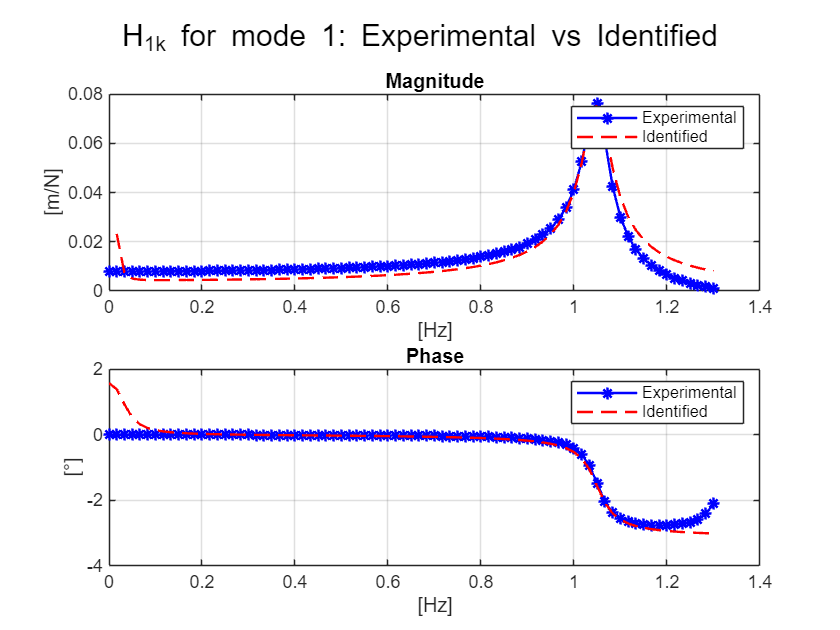

Frequency range


- fmin [Hz]: 1.3


- fmax [Hz]: 2.4


Number of points for the identification: 67


Initial guess f_0 [Hz]: 1.9666


Initial guess h [-]:    0.016098


Initial guess A_0 [m]: 0.43347


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000338 



vpar =     1.0000
    0.3161
  154.1006
    0.3795
   -0.0058
    0.0021
   -0.0032
    0.3138
   -0.1308


Modal parameters after minimization: mq22 = 1; kq22 = 0.31613; cq22 = 154.1006


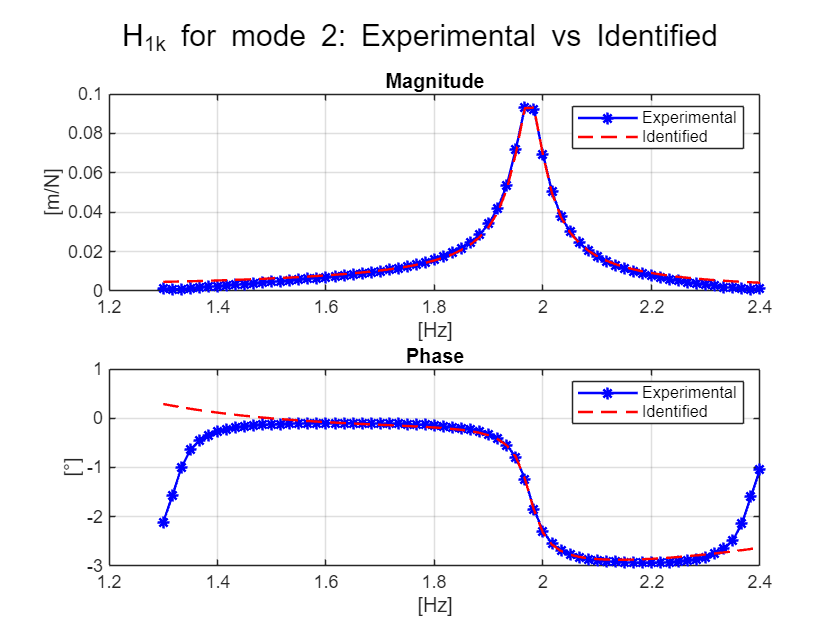

Frequency range


- fmin [Hz]: 2.4


- fmax [Hz]: 3


Number of points for the identification: 37


Initial guess f_0 [Hz]: 2.6666


Initial guess h [-]:    0.011303


Initial guess A_0 [m]: 0.38518


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000023 



vpar =     1.0000
    0.3322
  281.2161
    0.3396
    0.0011
    0.0121
    0.0015
   -0.5576
   -4.1050


Modal parameters after minimization: mq33 = 1; kq33 = 0.3322; cq33 = 281.2161


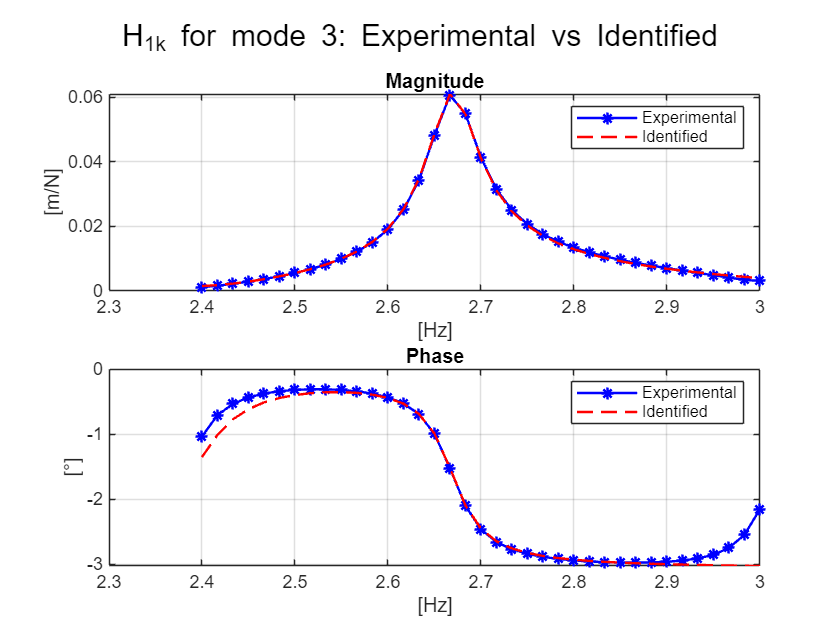

Frequency range


- fmin [Hz]: 3


- fmax [Hz]: 4.9999


Number of points for the identification: 121


Initial guess f_0 [Hz]: 3.0833


Initial guess h [-]:    0.014387


Initial guess A_0 [m]: 0.12091


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000008 



vpar =     1.0000
    0.3331
  371.9165
    0.0958
   -0.0136
    0.0017
    0.0003
   -0.2882
   -2.5306


Modal parameters after minimization: mq44 = 1; kq44 = 0.33309; cq44 = 371.9165


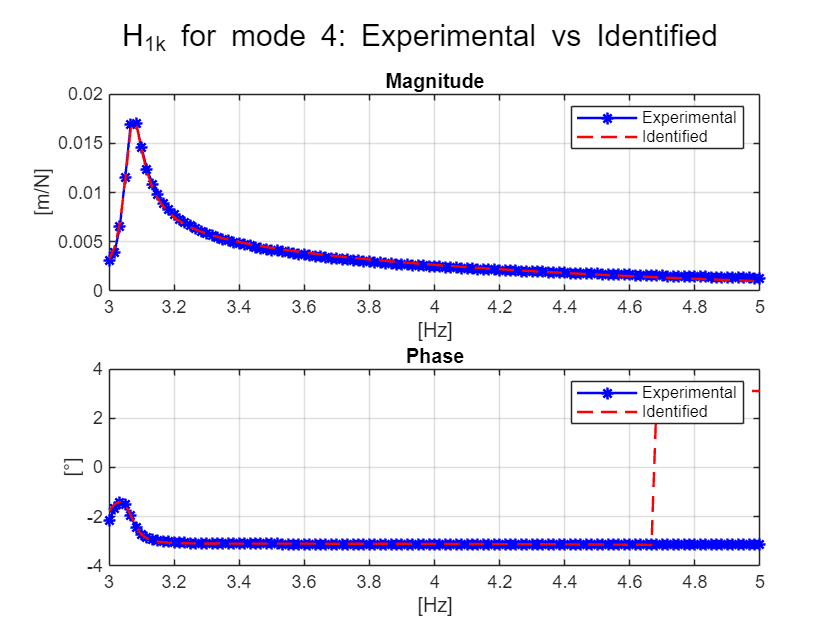

Frequency range


- fmin [Hz]: 0


- fmax [Hz]: 1.3


Number of points for the identification: 79


Initial guess f_0 [Hz]: 1.05


Initial guess h [-]:    0.028302


Initial guess A_0 [m]: 0.29276


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: Inf 



vpar =     1.0000
    0.3734
   43.5235
    0.2928
         0
         0
         0
    0.0003
         0


Modal parameters after minimization: mq11 = 1; kq11 = 0.37343; cq11 = 43.5235


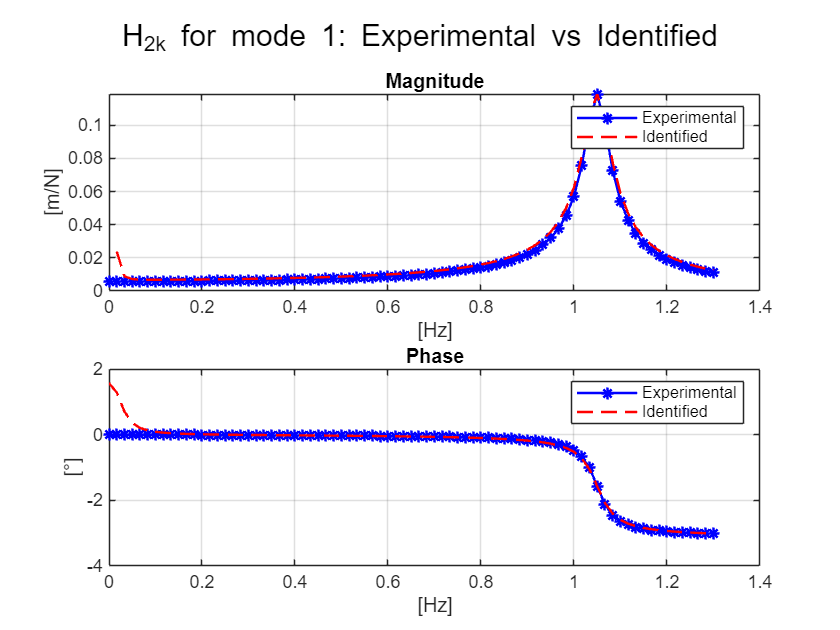

Frequency range


- fmin [Hz]: 1.3


- fmax [Hz]: 2.4


Number of points for the identification: 67


Initial guess f_0 [Hz]: 1.9833


Initial guess h [-]:    0.016028


Initial guess A_0 [m]: 0.20312


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000190 



vpar =     1.0000
    0.3267
  153.9424
    0.1808
    0.0050
   -0.0058
   -0.0015
    0.1545
   -0.1315


Modal parameters after minimization: mq22 = 1; kq22 = 0.32666; cq22 = 153.9424


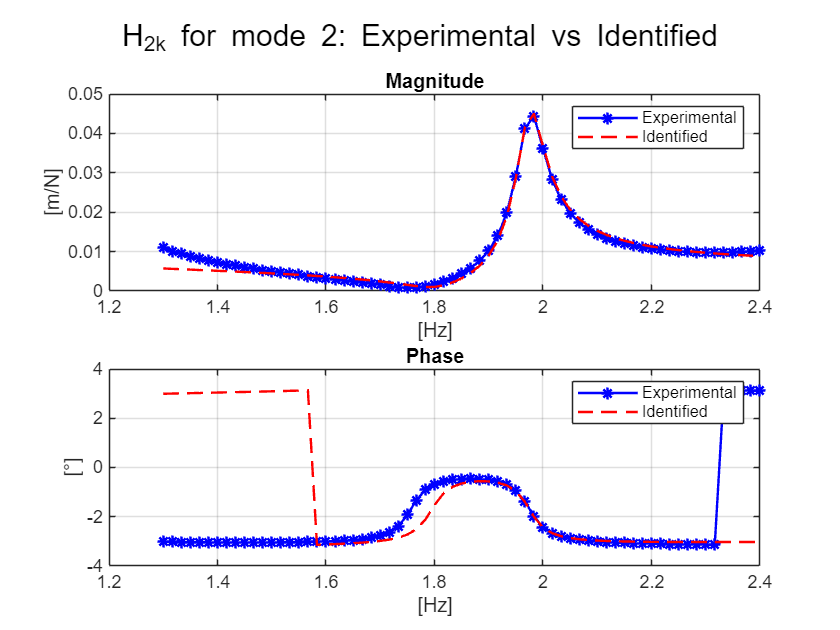

Frequency range


- fmin [Hz]: 2.4


- fmax [Hz]: 3


Number of points for the identification: 37


Initial guess f_0 [Hz]: 2.6666


Initial guess h [-]:    0.011311


Initial guess A_0 [m]: -0.31213


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000070 



vpar =     1.0000
    0.3244
  281.5723
   -0.2679
    0.0193
   -0.0068
    0.0079
   -2.0864
    0.2747


Modal parameters after minimization: mq33 = 1; kq33 = 0.32443; cq33 = 281.5723


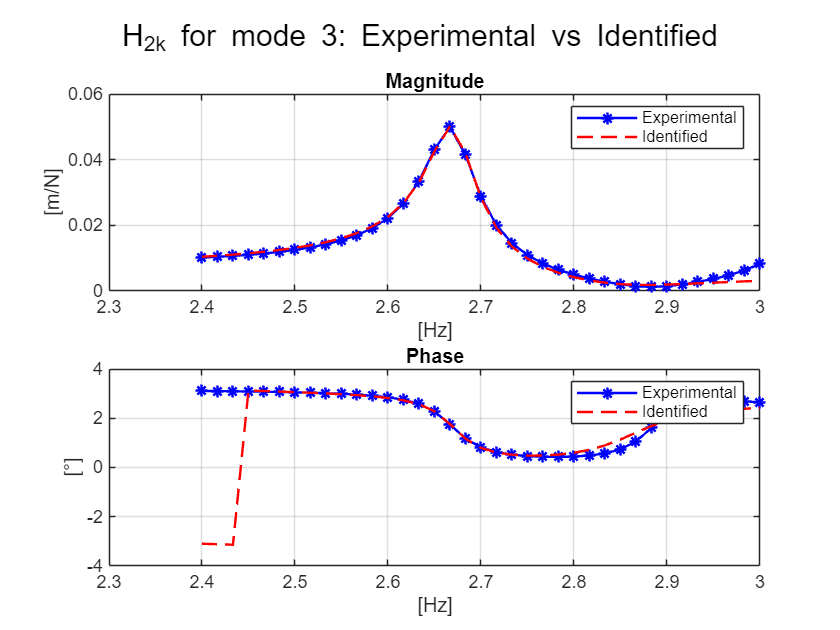

Frequency range


- fmin [Hz]: 3


- fmax [Hz]: 4.9999


Number of points for the identification: 121


Initial guess f_0 [Hz]: 3.0666


Initial guess h [-]:    0.0098626


Initial guess A_0 [m]: -0.1943


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000008 



vpar =     1.0000
    0.3449
  371.4864
   -0.1742
    0.0105
   -0.0005
    0.0004
   -0.2230
    0.3559


Modal parameters after minimization: mq44 = 1; kq44 = 0.34494; cq44 = 371.4864


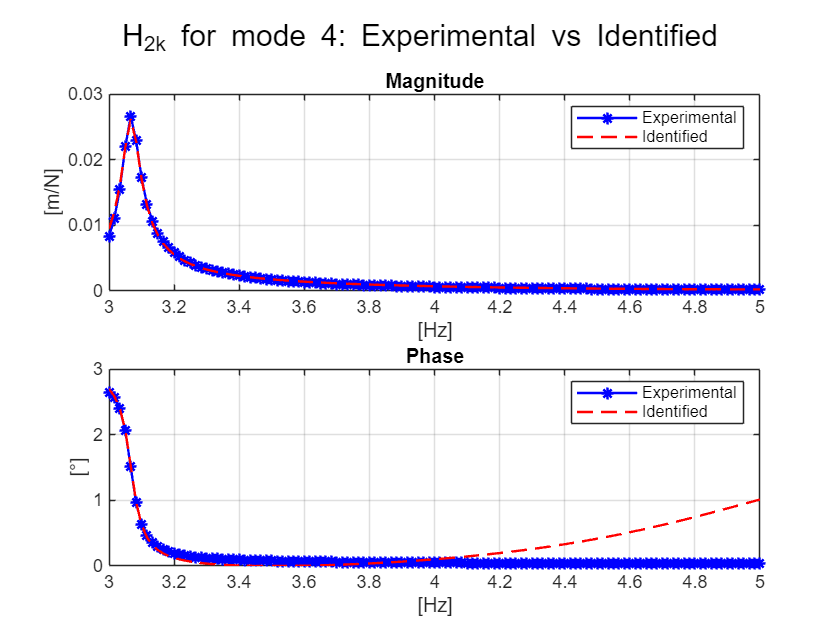

Frequency range


- fmin [Hz]: 0


- fmax [Hz]: 1.3


Number of points for the identification: 79


Initial guess f_0 [Hz]: 1.05


Initial guess h [-]:    0.028259


Initial guess A_0 [m]: 0.27038


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: Inf 



vpar =     1.0000
    0.3729
   43.5235
    0.2704
         0
         0
         0
    0.0003
         0


Modal parameters after minimization: mq11 = 1; kq11 = 0.37286; cq11 = 43.5235


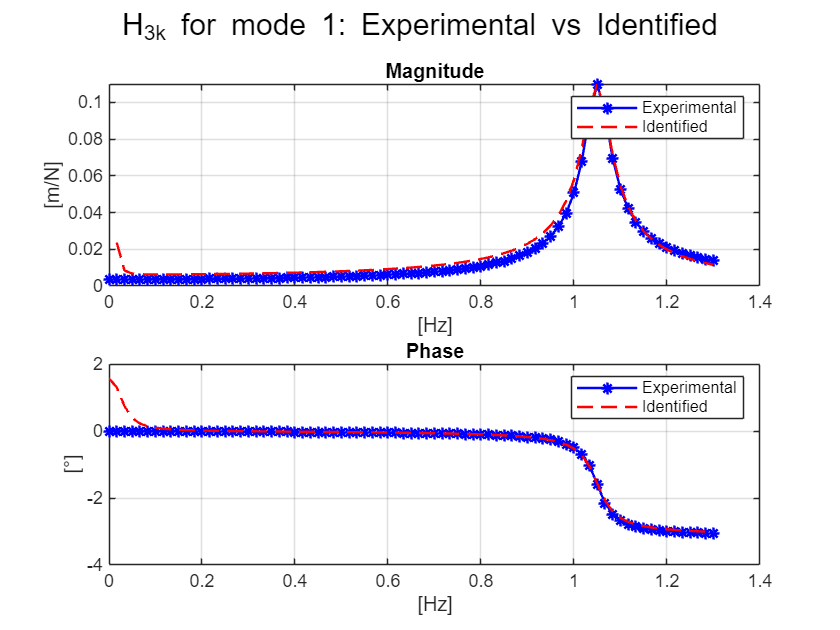

Frequency range


- fmin [Hz]: 1.3


- fmax [Hz]: 2.4


Number of points for the identification: 67


Initial guess f_0 [Hz]: 1.9666


Initial guess h [-]:    0.016018


Initial guess A_0 [m]: -0.33931


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000210 



vpar =     1.0000
    0.3452
  154.0810
   -0.3288
    0.0029
   -0.0018
   -0.0025
    0.2606
   -0.2107


Modal parameters after minimization: mq22 = 1; kq22 = 0.34516; cq22 = 154.081


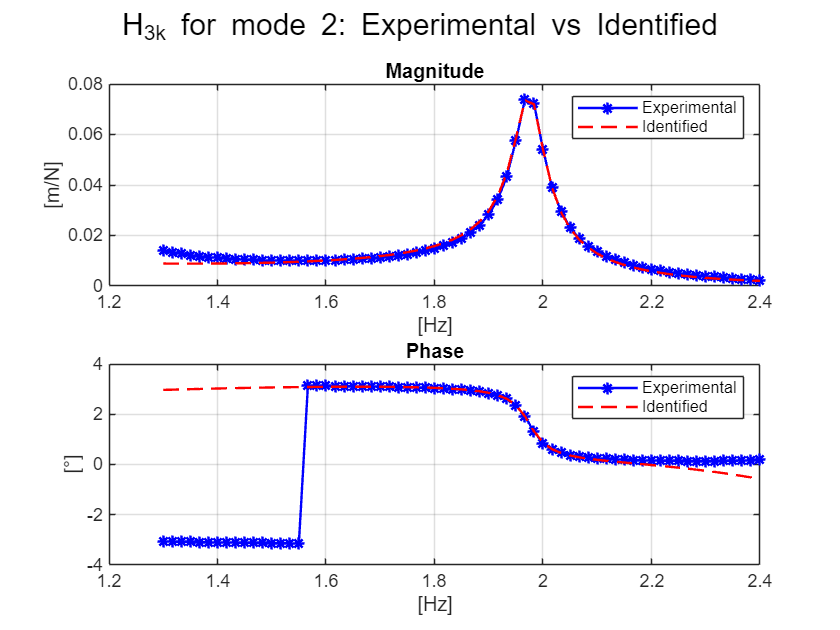

Frequency range


- fmin [Hz]: 2.4


- fmax [Hz]: 3


Number of points for the identification: 37


Initial guess f_0 [Hz]: 2.6666


Initial guess h [-]:    0.011504


Initial guess A_0 [m]: -0.13254


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000068 



vpar =     1.0000
    0.3320
  280.5181
   -0.1129
   -0.0178
    0.0144
   -0.0069
    1.8706
   -2.6424


Modal parameters after minimization: mq33 = 1; kq33 = 0.332; cq33 = 280.5181


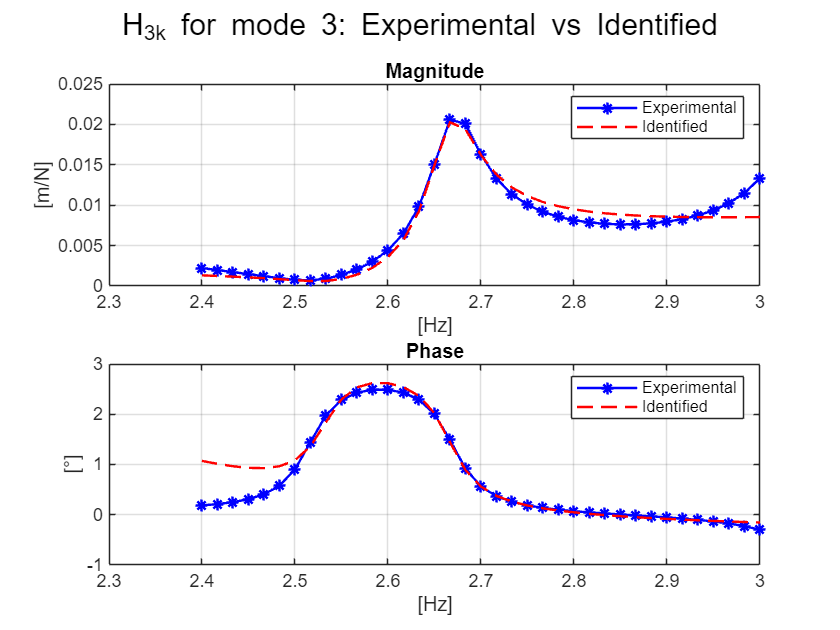

Frequency range


- fmin [Hz]: 3


- fmax [Hz]: 4.9999


Number of points for the identification: 121


Initial guess f_0 [Hz]: 3.0666


Initial guess h [-]:    0.0096574


Initial guess A_0 [m]: 0.21227


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000002 



vpar =     1.0000
    0.3299
  371.0750
    0.1892
    0.0045
   -0.0007
    0.0002
   -0.0902
    0.8327


Modal parameters after minimization: mq44 = 1; kq44 = 0.32987; cq44 = 371.075


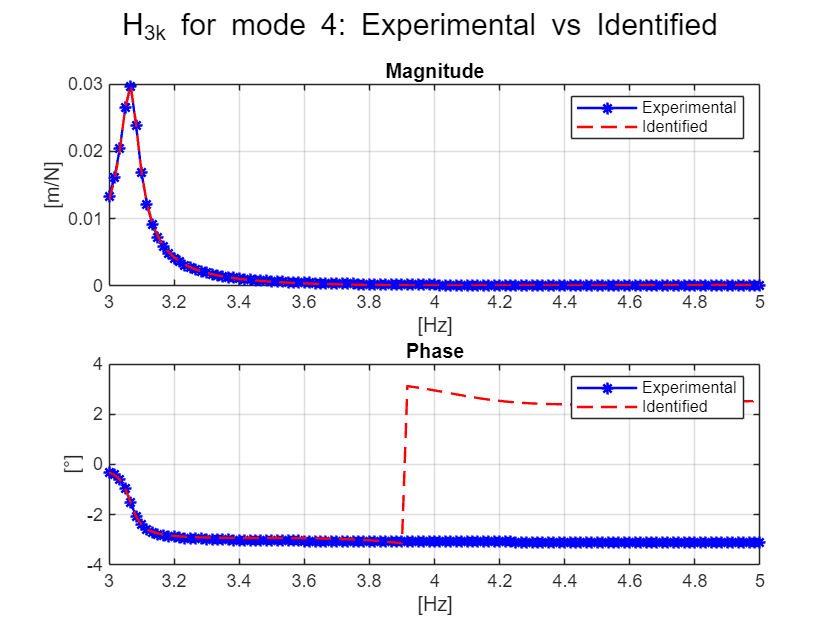

Frequency range


- fmin [Hz]: 0


- fmax [Hz]: 1.3


Number of points for the identification: 79


Initial guess f_0 [Hz]: 1.05


Initial guess h [-]:    0.028247


Initial guess A_0 [m]: 0.13085


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: Inf 



vpar =     1.0000
    0.3727
   43.5235
    0.1308
         0
         0
         0
    0.0003
         0


Modal parameters after minimization: mq11 = 1; kq11 = 0.3727; cq11 = 43.5235


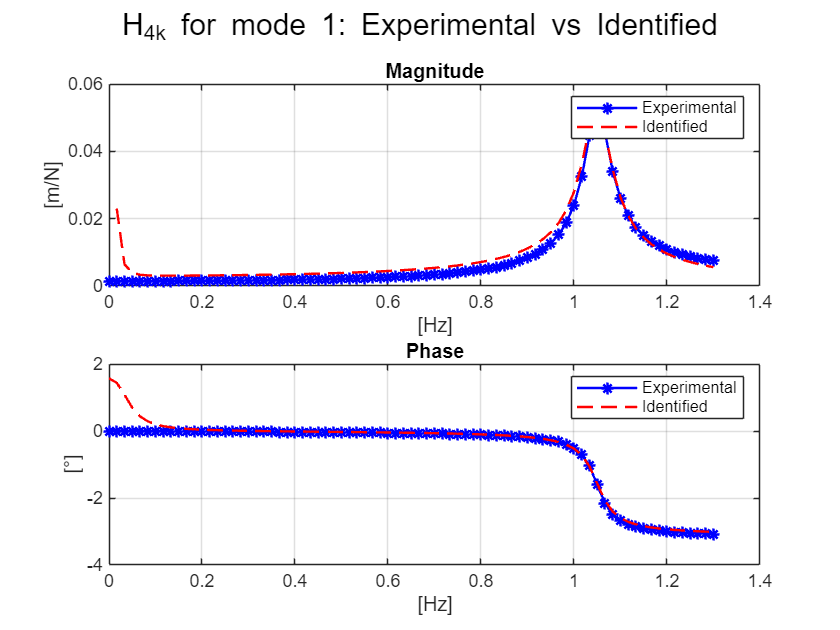

Frequency range


- fmin [Hz]: 1.3


- fmax [Hz]: 2.4


Number of points for the identification: 67


Initial guess f_0 [Hz]: 1.9833


Initial guess h [-]:    0.015753


Initial guess A_0 [m]: -0.35651


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000232 



vpar =     1.0000
    0.3518
  154.0615
   -0.3497
    0.0011
    0.0008
   -0.0013
    0.0927
   -0.0086


Modal parameters after minimization: mq22 = 1; kq22 = 0.35179; cq22 = 154.0615


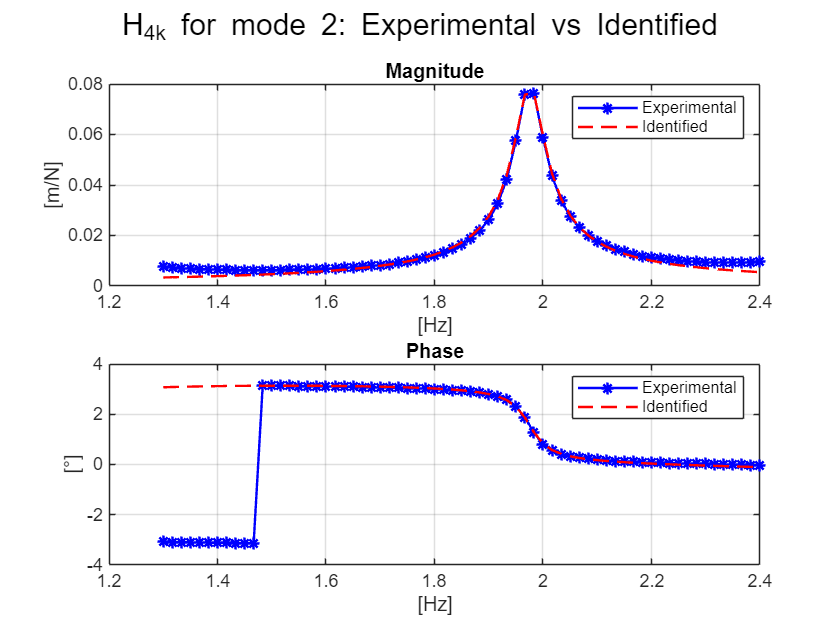

Frequency range


- fmin [Hz]: 2.4


- fmax [Hz]: 3


Number of points for the identification: 37


Initial guess f_0 [Hz]: 2.6666


Initial guess h [-]:    0.011111


Initial guess A_0 [m]: 0.40935


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000067 



vpar =     1.0000
    0.3356
  281.2582
    0.3730
   -0.0010
   -0.0154
   -0.0022
    0.7969
    4.2645


Modal parameters after minimization: mq33 = 1; kq33 = 0.33565; cq33 = 281.2582


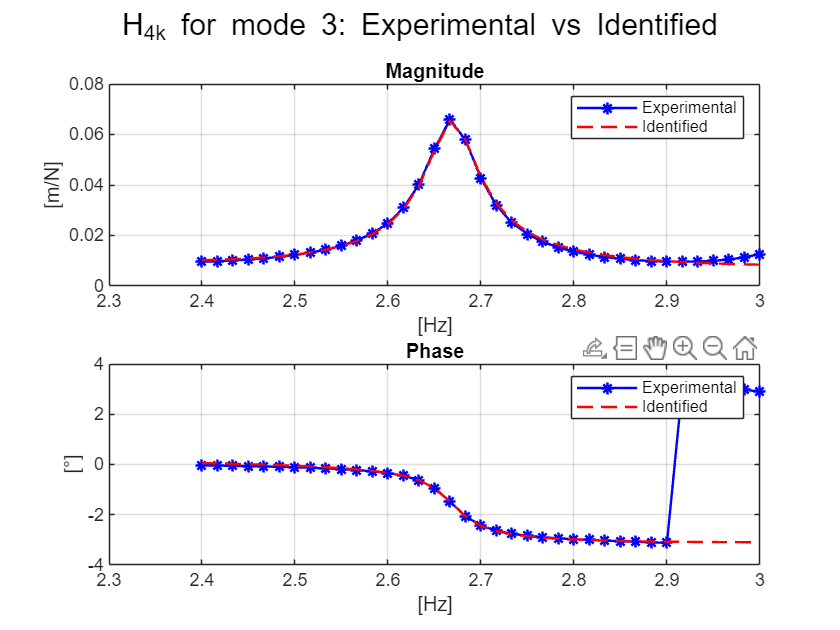

Frequency range


- fmin [Hz]: 3


- fmax [Hz]: 4.9999


Number of points for the identification: 121


Initial guess f_0 [Hz]: 3.0666


Initial guess h [-]:    0.0096322


Initial guess A_0 [m]: -0.17359


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000036 



vpar =     1.0000
    0.3138
  370.4464
   -0.1475
   -0.0218
   -0.0003
   -0.0008
    0.3724
   -0.2313


Modal parameters after minimization: mq44 = 1; kq44 = 0.31381; cq44 = 370.4464


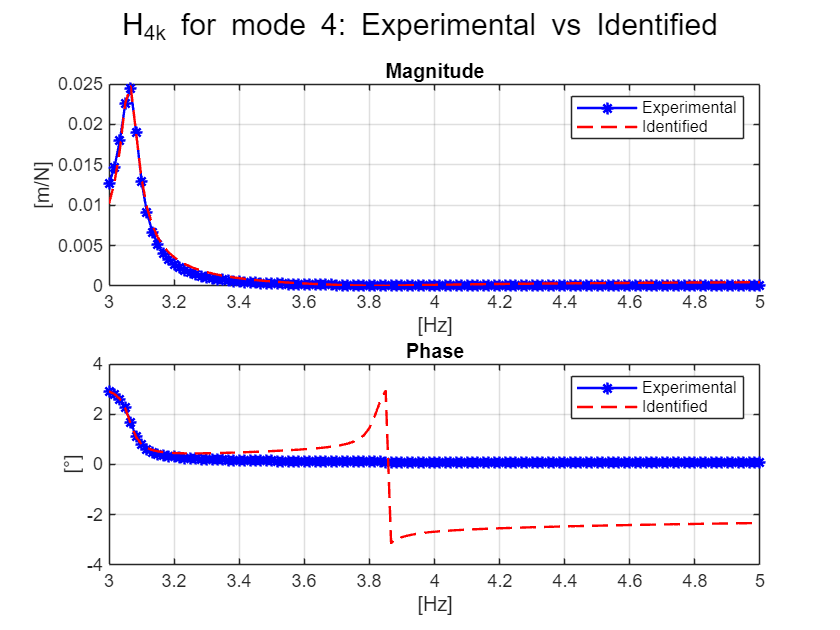


        % Filling of vector xpar
        xpar0 = [csii0; w0i0; Aj0; zeros(5,1)];    % Unknowns: 2 mod parameters + 6 constants
        % for the initial guess of the optimization
        
        % Identification: single channel    
        options = optimset('fminsearch');
        options = optimset(options,'TolFun',1e-8,'TolX',1e-8);
        xpar = fminsearch(@(xpar) errHjki_cw(xpar, rfHjki, Hjkiexp(:, jj)), xpar0, options);

        
        % @(xpar) parameter set we're trying to find
        % Error function (difference between experimental and optimized FRF)
        
        % Plot results of identification
        vpar = [1;    2*xpar(1)*xpar(2);    xpar(2)^2;    xpar(3:8)]
        %      [m;    c = 2 m w0 csi;       k = w0^2 m;  A;B;C;D;E;F]

        disp("Modal parameters after minimization: mq"+num2str(i)+num2str(i)+ " = " +num2str(vpar(1))+ "; kq"+num2str(i)+num2str(i)+ " = " + num2str(vpar(2)) + "; cq" +num2str(i)+num2str(i)+ " = " + num2str(vpar(3)) );


        %Extracting the modal parameters
        % Each 4 consecutives columns of res contain the modal parameters
        % of the same mode of vibration but for a different measurement
        % point
        res(:, jj + 4*(i-1)) = vpar(1:3);
        
        Hjkiid = funHjki(vpar, rfHjki);
        %Reconstructing the experimental FRF after solving the minimization
        %problem
        %rfHjki the frequency range of interest
        
        figure()
        sgtitle(['H_' num2str(jj) '_k for mode ' num2str(i) ': Experimental vs Identified'])
        
        subplot(2, 1, 1);
        plot(rfHjki, abs(Hjkiexp(:, jj)), '*b-', rfHjki, abs(Hjkiid), 'r--', 'linewidth', 1.2)
        grid on;
        title("Magnitude");
        ylabel("[m/N]");
        xlabel("[Hz]");
        legend("Experimental", "Identified");
        
        subplot(2, 1, 2);
        plot(rfHjki, angle(Hjkiexp(:, jj)), '*b-', rfHjki, angle(Hjkiid), 'r--', 'linewidth', 1.2)
        grid on;
        title("Phase");
        ylabel("[°]");
        xlabel("[Hz]");
        legend("Experimental", "Identified");
    end
end

## 4) Comparisons

Compare and comment the identified modal parameters with ones obtained with the above-mentioned methods.

%Using res my dawg
for j = 1:4        % for each FRF
    for i = 0:3
        disp(res(:, j+i*j))
    end
end

    1.0000
    0.3771
   43.5235

    1.0000
    0.3734
   43.5235

    1.0000
    0.3729
   43.5235

    1.0000
    0.3727
   43.5235

    1.0000
    0.3734
   43.5235

    1.0000
    0.3727
   43.5235

    1.0000
    0.3267
  153.9424

    1.0000
    0.3518
  154.0615

    1.0000
    0.3729
   43.5235

    1.0000
    0.3267
  153.9424

    1.0000
    0.3322
  281.2161

    1.0000
    0.3356
  281.2582

    1.0000
    0.3727
   43.5235

    1.0000
    0.3518
  154.0615

    1.0000
    0.3356
  281.2582

    1.0000
    0.3138
  370.4464




disp(res)

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.3771    0.3734    0.3729    0.3727    0.3161    0.3267    0.3452    0.3518    0.3322    0.3244    0.3320    0.3356    0.3331    0.3449    0.3299    0.3138
   43.5235   43.5235   43.5235   43.5235  154.1006  153.9424  154.0810  154.0615  281.2161  281.5723  280.5181  281.2582  371.9165  371.4864  371.0750  370.4464



## 5) Modal approach - FRF reconstruction

Employing a modal approach, reconstruct the FRFs and compare with the “experimental” original ones.